# PRM con REDD SHEPS CURVES

clear all; close all; clc;
% Carica la mappa da un file .mat (assumendo che contenga una variabile 'map')
data = load('map_straight_with_roundabout.mat');  % Sostituisci 'nome_file_mappa.mat' con il tuo percorso e nome del file

% Verifica i campi disponibili nella struttura 'data'
disp(fieldnames(data));

    {'map_straight_with_roundabout'}



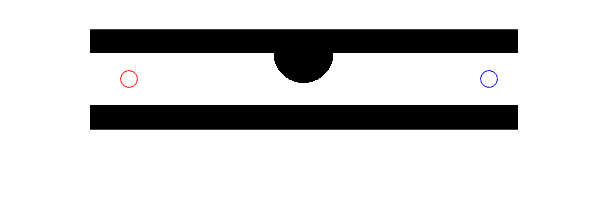


% Estrai la mappa dalla struttura dati
map = data.map_straight_with_roundabout;

% Assumi che la mappa caricata sia già una matrice binaria
% Se non lo è, bisogna convertirla in una mappa binaria
if ~islogical(map)
    map = imbinarize(map);  % Converte la mappa in un'immagine binaria
end

x_start = 40;
y_start = 50;
x_goal = 400;
y_goal = 50;

% Definizione di punti di partenza e arrivo
Qs = [x_start, y_start];  % Coordinata di partenza
Qg = [x_goal, y_goal];    % Coordinata di arrivo

% Plot initialization
figure;
imshow(map);
hold on;

% Plotting the start and goal points on the map
plot(x_start, y_start, 'ro', 'MarkerSize', 10); % Start point (red)
plot(x_goal, y_goal, 'bo', 'MarkerSize', 10); % Goal point (blue)

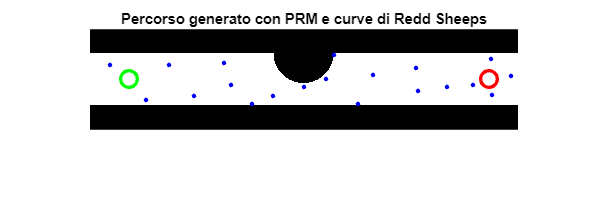


% Parametri per l'algoritmo PRM
numNodes = 20;         % Numero di punti campione
neighborRadius = 30;    % Raggio di ricerca per trovare vicini
minDist = 20;           % Distanza minima tra i punti campione
maxDist = 50;
curveResolution = 0.1;  % Risoluzione per l'interpolazione delle curve di Redd

% Genera punti campione casuali sulla mappa
samplePoints = generateRandomPoints(numNodes, map, minDist);

% Visualizza la mappa e il percorso
figure;
imshow(map);
hold on;
plot(Qs(1), Qs(2), 'go', 'MarkerSize', 10, 'LineWidth', 2);
plot(Qg(1), Qg(2), 'ro', 'MarkerSize', 10, 'LineWidth', 2);
% Plotting the sample points
plot(samplePoints(:, 1), samplePoints(:, 2), 'b.', 'MarkerSize', 8);  % Plot dei punti generati in blu

title('Percorso generato con PRM e curve di Redd Sheeps');
hold off;

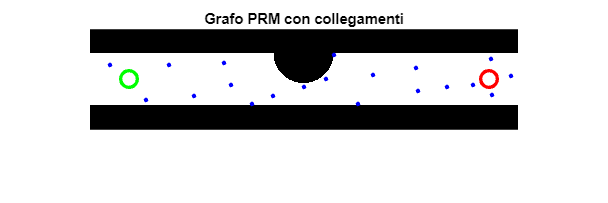


% Costruisci il grafo PRM
graph = buildPRMGraph(samplePoints, neighborRadius, minDist, map);

% Trova il percorso utilizzando A* o un altro algoritmo di ricerca del percorso
%pathNodes = findPathBFS(graph, Qs, Qg, neighborRadius, map);

% Interpola la traiettoria utilizzando le curve di Redd Sheeps
%smoothPath = interpolateReddSheeps(pathNodes, curveResolution);

% % Visualizza la mappa e i nodi
figure;
imshow(map);
hold on;
plot(Qs(1), Qs(2), 'go', 'MarkerSize', 10, 'LineWidth', 2);
plot(Qg(1), Qg(2), 'ro', 'MarkerSize', 10, 'LineWidth', 2);
% Plotting the sample points
plot(samplePoints(:, 1), samplePoints(:, 2), 'b.', 'MarkerSize', 8);  % Plot dei punti generati in blu
% Plot edges
for i = 1:length(graph.Edges)
    for j = 1:length(graph.Edges{i})
        pt1 = graph.Nodes(i, :);
        pt2 = graph.Nodes(graph.Edges{i}(j), :);
        plot([pt1(1), pt2(1)], [pt1(2), pt2(2)], 'b-'); % Blue lines for edges
    end
end
%line([nodes(i,2), nodes(j,2)], [nodes(i,1), nodes(j,1)], 'Color', 'k');
title('Grafo PRM con collegamenti');
hold off;

### FUNCTIONS

function points = generateRandomPoints(numPoints, map, minDist)
        
    [rows, cols] = size(map);
    points = [];
    navigableIndices = find(map == 1);  % Trova tutti gli indici navigabili
    totalNavigable = numel(navigableIndices);

    %% FIRST METHOD
    % % Inizializza un array per i punti candidati
    % candidatePoints = rand(numPoints, 2) .* [cols, rows];
    % 
    % % Inizializza un array per i punti validi
    % points = [];
    % 
    % % Loop attraverso i punti candidati per selezionare solo quelli validi
    % for i = 1:numPoints
    %     % Arrotonda le coordinate per ottenere indici validi per la mappa
    %     xIndex = round(candidatePoints(i, 1));
    %     yIndex = round(candidatePoints(i, 2));
    % 
    %     % Verifica che gli indici siano all'interno dei limiti della mappa
    %     if xIndex >= 1 && xIndex <= cols && yIndex >= 1 && yIndex <= rows
    %         % Verifica che il punto sia all'interno di un'area navigabile sulla mappa
    %         if map(yIndex, xIndex) == 1
    %             % Verifica delle distanze solo se ci sono punti già generati
    %             if ~isempty(points)
    %                 % Calcola le distanze tra il nuovo punto e tutti i punti esistenti
    %                 distances = sqrt(sum((points - candidatePoints(i, :)).^2, 2));
    % 
    %                 % Verifica che la distanza sia maggiore della distanza minima
    %                 if all(distances >= minDist)
    %                     points = [points; candidatePoints(i, :)];
    %                 end
    %             else
    %                 % Se non ci sono punti generati, aggiungi semplicemente il nuovo punto
    %                 points = [points; candidatePoints(i, :)];
    %             end
    %         end
    %     end
    % end


    % Loop finché non si generano abbastanza punti validi
    while size(points, 1) < numPoints

               %% 2 METHOD
        % Genera coordinate casuali
        newPoint = rand(1, 2) .* [cols, rows];

        % Arrotonda le coordinate per ottenere indici validi per la mappa
        xIndex = round(newPoint(1));
        yIndex = round(newPoint(2));

        % Verifica che gli indici siano all'interno dei limiti della mappa
        if xIndex >= 1 && xIndex <= cols && yIndex >= 1 && yIndex <= rows
            % Verifica che il punto sia all'interno di un'area navigabile sulla mappa
            if map(yIndex, xIndex) == 1
                % Verifica delle distanze solo se ci sono punti già generati
                if ~isempty(points)
                    % Calcola le distanze tra il nuovo punto e tutti i punti esistenti
                    distances = sqrt(sum((points - newPoint).^2, 2));

                    % Verifica che la distanza sia maggiore della distanza minima e minore della distanza massima
                    if all(distances >= minDist)  %&& all(distances <= maxDist)
                        points = [points; newPoint];
                    end
                else
                    % Se non ci sono punti generati, aggiungi semplicemente il nuovo punto
                    points = [points; newPoint];
                end
            end
        end
            
        %% 3 METHOD
        % % Seleziona un indice casuale tra i navigabili
        % randomIndex = navigableIndices(randi(totalNavigable));
        % [y, x] = ind2sub([rows, cols], randomIndex);
        % 
        % % Verifica che la distanza sia maggiore della distanza minima e minore della distanza massima
        % if isempty(points) || (all(sqrt(sum((points - [x, y]).^2, 2)) >= minDist)) %&& all(sqrt(sum((points - [x, y]).^2, 2)) <= maxDist)
        %     points = [points; x, y];
        % end
    end
end

function graph = buildPRMGraph(samplePoints, neighborRadius, minDist, map)
    % Costruisce il grafo PRM
    nPoints = size(samplePoints, 1);
    graph.Nodes = samplePoints;
    graph.Edges = cell(nPoints, 1);
    
    % Utilizza una ricerca spaziale per trovare vicini
    kdTree = KDTreeSearcher(samplePoints);
    for i = 1:nPoints
        % Trova i vicini entro il raggio specificato
        idx = rangesearch(kdTree, samplePoints(i,:), neighborRadius);
        
        % Valida i collegamenti e aggiungi archi validi al grafo
        for j = 1:length(idx{1})
            neighborIdx = idx{1}(j);
            if neighborIdx ~= i && all(minDist <= norm(samplePoints(i,:) - samplePoints(neighborIdx,:)))
                if isValidEdge(samplePoints(i,:), samplePoints(neighborIdx,:), map)
                    graph.Edges{i} = [graph.Edges{i}; neighborIdx];
                end
            end
        end
    end
end

function valid = isValidEdge(point1, point2, map)
    % Verifica se il collegamento tra point1 e point2 è valido sulla mappa
    line = [linspace(point1(1), point2(1), 50); linspace(point1(2), point2(2), 50)];
    x_line = round(line(1, :));
    y_line = round(line(2, :));
    
    % Verifica che ogni punto sulla linea non sia un ostacolo
    valid = all(map(sub2ind(size(map), y_line, x_line)) == 0);
end

% Function to find path using BFS
function path = findPathBFS(graph, start, goal, neighborRadius, map)
    nodes = [start; graph.Nodes; goal];
    nNodes = size(nodes, 1);
    
    % Update graph to include start and goal
    graph.Nodes = nodes;
    graph.Edges = [cell(1, 1); graph.Edges; cell(1, 1)];
    
    % Connect start and goal to the graph
    kdTree = KDTreeSearcher(nodes);
    for i = [1, nNodes]
        idx = rangesearch(kdTree, nodes(i, :), neighborRadius);
        for j = 1:length(idx{1})
            neighborIdx = idx{1}(j);
            if neighborIdx ~= i && isValidEdge(nodes(i, :), nodes(neighborIdx, :), map)
                graph.Edges{i} = [graph.Edges{i}; neighborIdx];
                graph.Edges{neighborIdx} = [graph.Edges{neighborIdx}; i];
            end
        end
    end
    
    % BFS to find the path
    queue = [1];
    visited = false(nNodes, 1);
    visited(1) = true;
    parent = zeros(nNodes, 1);
    
    while ~isempty(queue)
        currentNode = queue(1);
        queue(1) = [];
        
        if currentNode == nNodes
            break;
        end
        
        for i = 1:length(graph.Edges{currentNode})
            neighbor = graph.Edges{currentNode}(i);
            if ~visited(neighbor)
                visited(neighbor) = true;
                parent(neighbor) = currentNode;
                queue = [queue, neighbor];
            end
        end
    end
    
    % Reconstruct path
    if visited(nNodes)
        path = [];
        node = nNodes;
        while node ~= 0
            path = [node, path];
            node = parent(node);
        end
    else
        path = [];
    end
end
function smoothPath = interpolateReddSheeps(pathNodes, resolution)
    % Interpola la traiettoria utilizzando le curve di Redd Sheeps
    nPoints = size(pathNodes, 1);
    smoothPath = pathNodes(1, :);
    
    for i = 2:nPoints
        dist = norm(pathNodes(i, :) - pathNodes(i-1, :));
        numSegments = ceil(dist / resolution);
        x_interp = linspace(pathNodes(i-1, 1), pathNodes(i, 1), numSegments);
        y_interp = linspace(pathNodes(i-1, 2), pathNodes(i, 2), numSegments);
        smoothPath = [smoothPath; [x_interp(2:end-1)', y_interp(2:end-1)']];
    end
    
    smoothPath = [smoothPath; pathNodes(end, :)];
end
